%SPD -> mudança de sinal
%SPE -> o resto menos o A


%%%%%%%%%%%%%%%%%%% Exemplo 6.1 %%%%%%%%%%%%%%%%%%%
g=tf(1000,[1 10 31 1030])

g =
 
             1000
  --------------------------
  s^3 + 10 s^2 + 31 s + 1030
 
Continuous-time transfer function.
Model Properties



A=[1 31 0]

A =      1    31     0


B=[10 1030 0]

B =           10        1030           0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1) 0]

C =    -72     0     0


D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1) 0]

D =         1030           0           0


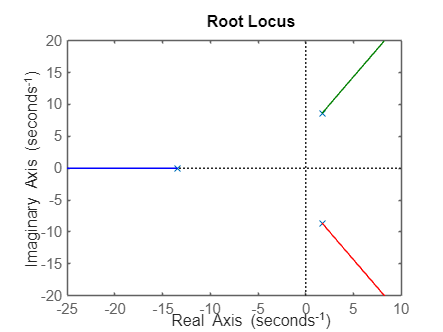

rlocus(g)

% 1 SPE
% 2 SPD

%%%%%%%%%%%%%%%%%%% Exercicio 6.1 %%%%%%%%%%%%%%%%%%%
g=tf(1,[3 9 6 4 7 8 2 6])

g =
 
                             1
  -------------------------------------------------------
  3 s^7 + 9 s^6 + 6 s^5 + 4 s^4 + 7 s^3 + 8 s^2 + 2 s + 6
 
Continuous-time transfer function.
Model Properties



A=[3 6 7 2 0]

A =      3     6     7     2     0


B=[9 4 8 6 0]

B =      9     4     8     6     0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1)...
-det([A(1) A(4) ;B(1) B(4)])/B(1) -det([A(1) A(5) ;B(1) B(5)])/B(1) 0]

C =     4.6667    4.3333         0         0         0


D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1)...
-det([B(1) B(4) ;C(1) C(4)])/C(1) -det([B(1) B(5) ;C(1) C(5)])/C(1) 0]

D =    -4.3571    8.0000    6.0000         0         0


E=[-det([C(1) C(2) ;D(1) D(2)])/D(1) -det([C(1) C(3) ;D(1) D(3)])/D(1)...
-det([C(1) C(4) ;D(1) D(4)])/D(1) -det([C(1) C(5) ;D(1) D(5)])/D(1) 0]

E =    12.9016    6.4262         0         0         0


F=[-det([D(1) D(2) ;E(1) E(2)])/E(1) -det([D(1) D(3) ;E(1) E(3)])/E(1)...
-det([D(1) D(4) ;E(1) E(4)])/E(1) -det([D(1) D(5) ;E(1) E(5)])/E(1) 0]

F =    10.1703    6.0000         0         0         0


G=[-det([E(1) E(2) ;F(1) F(2)])/F(1) -det([E(1) E(3) ;F(1) F(3)])/F(1)...
-det([E(1) E(4) ;F(1) F(4)])/F(1) -det([E(1) E(5) ;F(1) F(5)])/F(1) 0]

G =    -1.1852         0         0         0         0


H=[-det([F(1) F(2) ;G(1) G(2)])/G(1) -det([F(1) F(3) ;G(1) G(3)])/G(1)...
-det([F(1) F(4) ;G(1) G(4)])/G(1) -det([F(1) F(5) ;G(1) G(5)])/G(1) 0]

H =      6     0     0     0     0


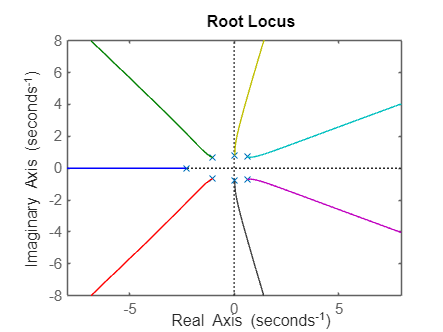

%4 SPD
%3 SPE
rlocus(g)


%%%%%%%%%%%%%%%%%%% Exemplo 6.2 %%%%%%%%%%%%%%%%%%%
g=tf(10,[1 2 3 6 5 3])

g =
 
                   10
  -------------------------------------
  s^5 + 2 s^4 + 3 s^3 + 6 s^2 + 5 s + 3
 
Continuous-time transfer function.
Model Properties



e = 0.0001

e = 1.0000e-04


A=[1 3 5 0]

A =      1     3     5     0


B=[2 6 3 0]

B =      2     6     3     0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1)...
-det([A(1) A(4) ;B(1) B(4)])/B(1) 0];
C=[e 3.5 0 0]

C =     0.0001    3.5000         0         0


D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1)...
-det([B(1) B(4) ;C(1) C(4)])/C(1) 0]

D =       -69994           3           0           0


E=[-det([C(1) C(2) ;D(1) D(2)])/D(1) -det([C(1) C(3) ;D(1) D(3)])/D(1)...
-det([C(1) C(4) ;D(1) D(4)])/D(1) 0]

E =     3.5000         0         0         0


F=[-det([D(1) D(2) ;E(1) E(2)])/E(1) -det([D(1) D(3) ;E(1) E(3)])/E(1)...
-det([D(1) D(4) ;E(1) E(4)])/E(1) 0]

F =     3.0000         0         0         0


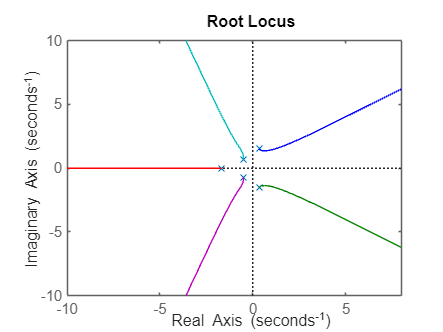

rlocus(g)

%SPE = 3
%SPD = 2

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
g=tf([1 8],[1 -1 3 3 3 -2])

g =
 
                 s + 8
  -----------------------------------
  s^5 - s^4 + 3 s^3 + 3 s^2 + 3 s - 2
 
Continuous-time transfer function.
Model Properties



A=[1 3 3 0]

A =      1     3     3     0


B=[-1 -3 -2 0]

B =     -1    -3    -2     0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1)...
-det([A(1) A(4) ;B(1) B(4)])/B(1) 0];
C=[e -det([A(1) A(3) ;B(1) B(3)])/B(1)...
-det([A(1) A(4) ;B(1) B(4)])/B(1) 0]

C =     0.0001    1.0000         0         0


D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1)...
-det([B(1) B(4) ;C(1) C(4)])/C(1) 0]

D =         9997          -2           0           0


E=[-det([C(1) C(2) ;D(1) D(2)])/D(1) -det([C(1) C(3) ;D(1) D(3)])/D(1)...
-det([C(1) C(4) ;D(1) D(4)])/D(1) 0]

E =     1.0000         0         0         0


F=[-det([D(1) D(2) ;E(1) E(2)])/E(1) -det([D(1) D(3) ;E(1) E(3)])/E(1)...
-det([D(1) D(4) ;E(1) E(4)])/E(1) 0]

F =     -2     0     0     0


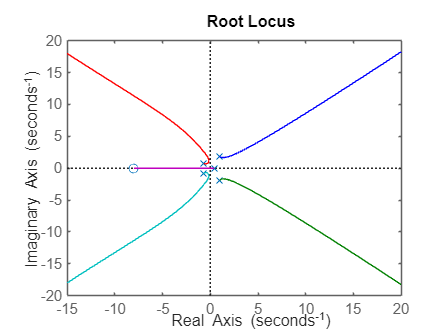

rlocus(g)

%SPE = 2
%SPD = 3

%%%%%%%%%%%%%%%%%%% Exemplo 6.4 %%%%%%%%%%%%%%%%%%%
g=tf(10,[1 7 6 42 8 56])

g =
 
                    10
  ---------------------------------------
  s^5 + 7 s^4 + 6 s^3 + 42 s^2 + 8 s + 56
 
Continuous-time transfer function.
Model Properties



A=[1 6 8 0]

A =      1     6     8     0


B=[7 42 56 0]

B =      7    42    56     0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1)...
-det([A(1) A(4) ;B(1) B(4)])/B(1) 0];
C=[28 84 0 0]

C =     28    84     0     0


D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1)...
-det([B(1) B(4) ;C(1) C(4)])/C(1) 0]

D =     21    56     0     0


E=[-det([C(1) C(2) ;D(1) D(2)])/D(1) -det([C(1) C(3) ;D(1) D(3)])/D(1)...
-det([C(1) C(4) ;D(1) D(4)])/D(1) 0]

E =     9.3333         0         0         0


F=[-det([D(1) D(2) ;E(1) E(2)])/E(1) -det([D(1) D(3) ;E(1) E(3)])/E(1)...
-det([D(1) D(4) ;E(1) E(4)])/E(1) 0]

F =    56.0000         0         0         0


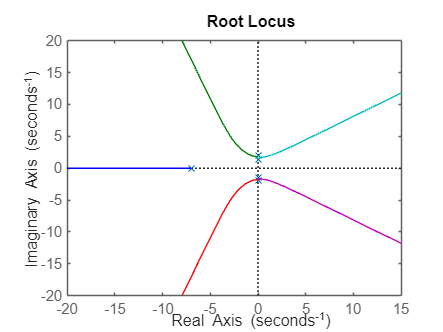


rlocus(g)

% SPD = 0
% SPE = 1
% EIXO = 4

%%%%%%%%%%%%%%%%%%% Exemplo 6.5 %%%%%%%%%%%%%%%%%%%
g=tf(20,[1 1 12 22 39 59 48 38 20])

g =
 
                                  20
  ------------------------------------------------------------------
  s^8 + s^7 + 12 s^6 + 22 s^5 + 39 s^4 + 59 s^3 + 48 s^2 + 38 s + 20
 
Continuous-time transfer function.
Model Properties


A=[1 12 39 48 20]

A =      1    12    39    48    20


B=[1 22 59 38 0]

B =      1    22    59    38     0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1)...
-det([A(1) A(4) ;B(1) B(4)])/B(1) -det([A(1) A(5) ;B(1) B(5)])/B(1) 0]

C =    -10   -20    10    20     0


D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1)...
-det([B(1) B(4) ;C(1) C(4)])/C(1) -det([B(1) B(5) ;C(1) C(5)])/C(1) 0]

D =     20    60    40     0     0


E=[-det([C(1) C(2) ;D(1) D(2)])/D(1) -det([C(1) C(3) ;D(1) D(3)])/D(1)...
-det([C(1) C(4) ;D(1) D(4)])/D(1) -det([C(1) C(5) ;D(1) D(5)])/D(1) 0]

E =     10    30    20     0     0


F=[-det([D(1) D(2) ;E(1) E(2)])/E(1) -det([D(1) D(3) ;E(1) E(3)])/E(1)...
-det([D(1) D(4) ;E(1) E(4)])/E(1) -det([D(1) D(5) ;E(1) E(5)])/E(1) 0];
%F = 10*s^4+30+s^2+20
%devirada 40*s^3+60*s^1
F=[40 60 0 0 0] 

F =     40    60     0     0     0


G=[-det([E(1) E(2) ;F(1) F(2)])/F(1) -det([E(1) E(3) ;F(1) F(3)])/F(1)...
-det([E(1) E(4) ;F(1) F(4)])/F(1) -det([E(1) E(5) ;F(1) F(5)])/F(1) 0]

G =     15    20     0     0     0


H=[-det([F(1) F(2) ;G(1) G(2)])/G(1) -det([F(1) F(3) ;G(1) G(3)])/G(1)...
-det([F(1) F(4) ;G(1) G(4)])/G(1) -det([F(1) F(5) ;G(1) G(5)])/G(1) 0]

H =     6.6667         0         0         0         0


I=[-det([G(1) G(2) ;H(1) H(2)])/H(1) -det([G(1) G(3) ;H(1) H(3)])/H(1)...
-det([G(1) G(4) ;H(1) H(4)])/H(1) -det([G(1) G(5) ;H(1) H(5)])/H(1) 0]

I =     20     0     0     0     0


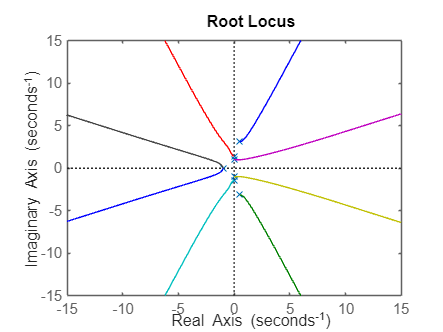


rlocus(g)

% SPD = 2
% SPE = 2
% EIXO = 4

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

g=tf(1,[1 6 5 8 20])

g =
 
                1
  ------------------------------
  s^4 + 6 s^3 + 5 s^2 + 8 s + 20
 
Continuous-time transfer function.
Model Properties


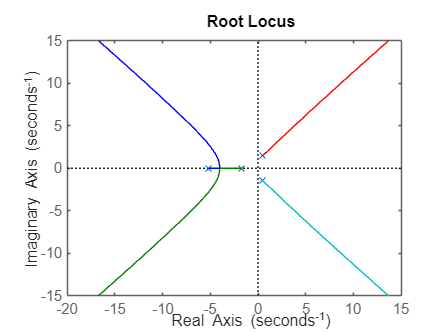

rlocus(g)

% SPD = 2
% SPE = 2
% EIXO jw = 0

%%%%%%%%%%%%%%%%%%% Exercicio 6.2 %%%%%%%%%%%%%%%%%%%
g=tf([1 7 -21 10],[1 1 -6 0 -1 -1 6])

g =
 
      s^3 + 7 s^2 - 21 s + 10
  -------------------------------
  s^6 + s^5 - 6 s^4 - s^2 - s + 6
 
Continuous-time transfer function.
Model Properties



A=[1 -6 -1 6]

A =      1    -6    -1     6


B=[1 0 -1 0]

B =      1     0    -1     0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1)...
-det([A(1) A(4) ;B(1) B(4)])/B(1) 0]

C =     -6     0     6     0


% -6*s^4 - 6*s^0
% -24
D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1)...
-det([B(1) B(4) ;C(1) C(4)])/C(1) 0];
D=[-24 0 0 0]

D =    -24     0     0     0


E=[-det([C(1) C(2) ;D(1) D(2)])/D(1) -det([C(1) C(3) ;D(1) D(3)])/D(1)...
-det([C(1) C(4) ;D(1) D(4)])/D(1) 0];
E=[e 6 0 0]

E =     0.0001    6.0000         0         0


F=[-det([D(1) D(2) ;E(1) E(2)])/E(1) -det([D(1) D(3) ;E(1) E(3)])/E(1)...
-det([D(1) D(4) ;E(1) E(4)])/E(1) 0]

F =      1440000           0           0           0


G=[-det([E(1) E(2) ;F(1) F(2)])/F(1) -det([E(1) E(3) ;F(1) F(3)])/F(1)...
-det([E(1) E(4) ;F(1) F(4)])/F(1) 0]

G =      6     0     0     0


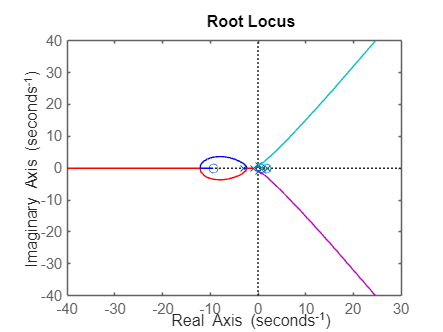


rlocus(g)


% SPD = 2
% SPE = 2
% Eixo jw = 2


%%%%%%%%%%%%%%%%%%% Exemplo 6.9 %%%%%%%%%%%%%%%%%%%

syms k

%g=tf(k,[1 18 77 k])
A=[1 77 0]

A =      1    77     0


B=[18 k 0]

$$B = \left(\begin{array}{ccc} 18 & k & 0 \end{array}\right)$$

C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1) 0]

$$C = \left(\begin{array}{ccc} 77-\frac{k}{18} & 0 & 0 \end{array}\right)$$

D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1) 0]

$$D = \left(\begin{array}{ccc} \frac{k\,\left(k-1386\right)}{18\,\left(\frac{k}{18}-77\right)} & 0 & 0 \end{array}\right)$$



rlocus(g)